# 2. aet2-Klausur  2Ea/2Eb  vom  4.6.2014

## 2.

clear all; clc
U12_ = 120*cis(-20, 'grad');
U23_ = 230*cis(20, 'grad');
U34_ = 180*cis(90, 'grad');
I2_ = 2*cis(30, 'grad');
I3_ = 3*cis(40, 'grad');
I4_ = 4*cis(50, 'grad');

P2 = real(-U12_*I2_')

P2 = -154.2690

P3 = real((-U12_-U23_)*I3_')

P3 = -828.3879

P4 = real((-U12_-U23_-U34_)*I4_')

P4 = -1.5125e+03


P = P2+P3+P4

P = -2.4951e+03

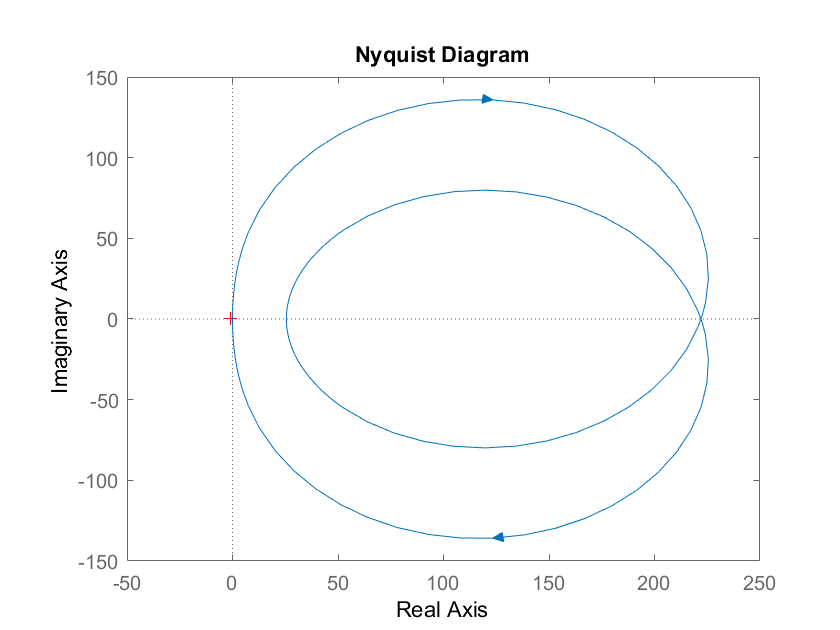

clear all; clc
L = 25e-6;
C = 2200e-12;
R1 = 470;
R2 = 27;

s = tf('s');
HZ = 1/( 1/R1 + s*C + 1/(R2 + s*L) );
nyquist(HZ)


w0 = 1/sqrt(L*C);
Ql = w0*L/R2

Ql = 3.9482

Ql = 1/R2 * sqrt(L/C)

Ql = 3.9482

wr = w0 * sqrt(1-1/(Ql^2))

wr = 4.1250e+06

% Kontrolle
w=wr;
Z_ = 1/ ( 1/R1 + j*w*C + 1/(R2 + j*w*L) )

Z_ = 2.2204e+02 - 8.5526e-14i


U_ = 20/sqrt(2) * cis(0, 'grad');
w=2*pi*500e3;
Z_ = 1/ ( 1/R1 + j*w*C + 1/(R2 + j*w*L) );
P = U_^2 * real(1/Z_)

P = 1.2084

S_ = U_^2 * (1/Z_)'

S_ = 1.2084 + 0.8950i

## 5.

clear all; clc
syms R1 R2;
gl1 = 50 == 1/( 1/R1 + 1/(R2+100) );
gl2 = 100 == 1/( 1/(50) + 1/(R1) ) + R2;
assume(R2, 'positive');
assume(R1, 'positive');
lsg=solve(gl1, gl2)

lsg = struct with fields:
    R1: [1×1 sym]
    R2: [1×1 sym]


lsg.R1

$$ans = 50\,\sqrt{2}$$

lsg.R2

$$ans = 50\,\sqrt{2}$$